# Projektiranje sustava upravljanja brzinom vrtnje DC motora korištenjem diskretnog TG postupka

Istosmjerni (DC) motor opisan je linearnim modelom drugog reda oblika:


$$G_p(s)=\frac{K}{(1+T_1s)(1+T_2s)}$$


pri čemu je $K=10$, $T_1=5ms$ i $T_2=30ms$. Potrebno je projektirati diskretni TG regulator kako bi se postiglo vladanje prema prototipnom Butterworthovom obliku uz $t_m=10ms$:

tm=10e-3;
K=10;
T1=5e-3;
T2=30e-3;
Gp=tf(K,conv([T1 1],[T2 1])) %Proces

Gp =
 
             10
  -------------------------
  0.00015 s^2 + 0.035 s + 1
 
Continuous-time transfer function.



Proces se za potrebe projektiranja regulatora diskretnim TG postupkom diskretizira primjenom ZOH diskretizacije:


$$Gp(z)=(1-z^{-1})\mathcal{Z}\left\{\frac{G(s)}{s}\right\}$$


T=0.002;
Gpd=c2d(Gp,T,'zoh')%Diskretizirani proces

Gpd =
 
    0.1146 z + 0.09806
  ----------------------
  z^2 - 1.606 z + 0.6271
 
Sample time: 0.002 seconds
Discrete-time transfer function.



%pzmap(Gpd)

## Kontinuirani TG regulator

Na temelju prijenosne funkcije procesa $G_p(s)$te zahtjeva na vladanje sustava definira se ostvariva modelska funkcija zatvorenog regulacijskog kruga.

Kako je polni višak procesa $n-m=2$ slijedi da i modelska prijenosna funkcija mora imati polani višak najmanje istog iznosa. Stoga biramo prototipni Butterworthov oblik vladanja 2. reda.

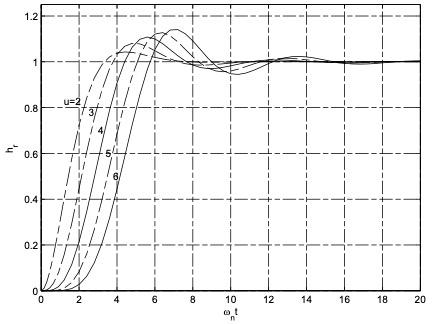 Iz grafa se može očitati da se vrijeme prvog maksimuma za sustav drugor reda postiže za $\omega_n t_m=4.3$ odakle slijedi da je prirodna frekvencija neprigušenih oscilacija jednaka $\omega_n$ jednaka:

omg0=4.3/tm;

Prema tome modelska prijenosna funkcija zatvorenog regulacijskog kruga je jednaka:


$$G_m(s)=\frac{\omega_n^2}{s^2+1.4\omega_n s+\omega_n^2}$$


Gm=tf(omg0^2,[1 1.4*omg0 omg0^2]);
Gr=minreal(1/Gp*Gm/(1-Gm));
Grz=minreal(Gr*Gp/(1+Gr*Gp));
[hc,tc]=step(Grz,0.04); %Prijelazna funkcija procesa
%figure, step(Grz)

## Emulacija kontinuranog regulatora

Emulacija kontinuiranog regulatora provodi se numeričkom diskretizacijom regulatora primjenom nekog od aproksimativnih postupaka diskretizacije kao što su Eulerovi postupci unaprijedne i unazadne diferencijacije i Tustinov postupak. U ovom primjeru koristimo Tustinov postupak:

Grde1=c2d(Gr,T,'Tustin');%diskretizacija regulatra
Grzde1=minreal(Grde1*Gpd/(1+Grde1*Gpd));
[hd1,td1]=step(Grzde1);

Usporedba kontinuiranog i diskretnog regulatora dobivenog metodom emulacije kontinuiranog regulatora prikazana je na slici.

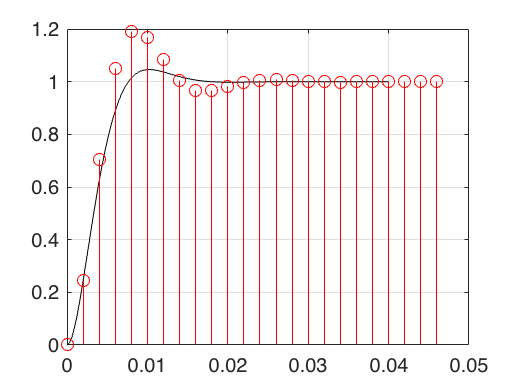

figure
plot(tc,hc,'k'), grid on, hold on;
stem(td1,hd1,'r');

## Diskretni TG regulator

Željeno vladanje definira se diskretnom modelskom prijenosnom funkcijom koja se proračunava na temelju kontinuirane modelske prijenosne funkcije. Na temelje polinoma $A_m(z)$  računaju se polovi kontinuirane modelske funkcije koji se zatim preslikavaju prema izrazu $z=e^{sT}$.

p=roots([1 1.4*omg0 omg0^2]); %polovi od Am
pz=exp(p*T); %Preslikavanje polova
Amz=poly(pz); %Formiranje polinoma Am(z)

Polinom brojnika modelske funckcije određujemo da zadovoljhim zahtjeve na stacionarnu točnost kao i eleminaciju oscilacija između trenutaka uzorkovanja (engl. intersample ripples). Kako je polni višak doskretnog modela procesa jednak 1 tada polinom $B_m(z)$pretpostavljamo u obliku polinoma prvog reda $B_m(z)=b_{m1}z+b_{m0}$

Uvjet stacionarne točnosti modelske funkcije glasi (odziv nastep pobudu u stacionarnom stanju ima vrijednost 1):


$$\lim_{z\to1}{(z-1)G_(z)\frac{z}{z-1}}=G_m(1)=1$$
 

odnosno $b_{m1}+b_{m0}=1+a_{m1}+a_{m0}$. 

Očito postoji beskonačno rješenja uz koje je zadovoljen uvjet. Stoga možemo odabrati $b_{m0}=0$ odakle slijedi da je $b_{m1}=1+a_{m1}+a_{m1}$

b1m=sum(Amz);
b0m=0;
Bmz=[b1m b0m];
Gmz=tf(Bmz,Amz,T);
Grd=minreal(1/Gpd*Gmz/(1-Gmz));% Regulator u z-domeni

Simulacijom sustava upravljanja uz ovako određen regulator se dobiju odzivi prikazani na slici.

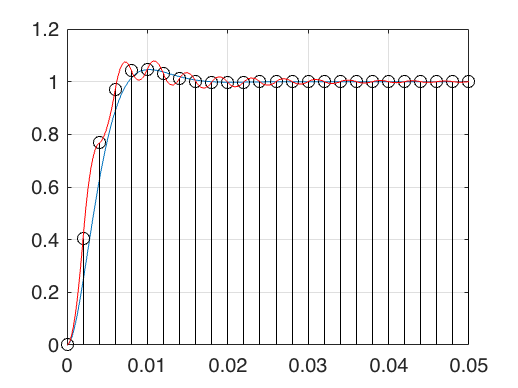

sim('Diskretni_TG_test.slx');
figure
plot(out.tc,out.yc), grid, hold on;
stem(out.td,out.ydT,'k');
plot(out.tc,out.yd,'r');

Drugi uvjet je da polinom $B_m(z)$sadrži diskretizacijsku nulu procesa zbog toga što kraćenje te nule rezultira uvođenjem pola regulatora na toj lokaciji koji ima za posljedicu oscilatorno vladanje upravljačke veličine odnosno oscilacija između trenutaka uzrokovanja. Nultočka procesa $z=-b_0/b_1$treba biti nultočaka $B_m(z)$, tj. $-b_{m1}b_0/b_1+b_{m0}=0$, odakle slijedi:


$$b_{m1}+b_{m1}b_0/b_1=1+a_{m1}+a_{m0}$$


odnosno:


$$b_{m0}=\frac{b_0}{b_1+b_0}(1+a_{m1}+a_{m0})$$



$$b_{m1}=\frac{b_1}{b_1+b_0}(1+a_{m1}+a_{m0})$$


bp0=Gpd.Numerator{1}(3);
bp1=Gpd.Numerator{1}(2);
b1m=bp1/(bp1+bp0)*sum(Amz);
b0m=bp0/(bp1+bp0)*sum(Amz);
Bmz=[b1m b0m];
Gmz=tf(Bmz,Amz,T)

Gmz =
 
   0.2181 z + 0.1867
  --------------------
  z^2 - 0.8952 z + 0.3
 
Sample time: 0.002 seconds
Discrete-time transfer function.



Regulator se konačno proračunava prema izrazu:


$$G_R(z)=\frac{1}{G_p(z)}\frac{G_m(z)}{1-G_m(z)}$$


Grd=minreal(1/Gpd*Gmz/(1-Gmz));% Regulator u z-domeni
Grzd=minreal(Grd*Gpd/(1+Grd*Gpd),1e-3);% Zatv. reg. krug prema referenci
[hd2,td2]=step(Grzd);

Usporedba kontinuiranog i diskretnog regulatora dobivenog diskretnim TG postupkom prikazana je na slici.

sim('Diskretni_TG_test.slx');
figure
plot(out.tc,out.yc), grid, hold on;
stem(out.td,out.ydT,'k');
plot(out.tc,out.yd,'r');

Vidljivo je da sada nema oscilacija između trenutaka uzorkovanja jer je sada diskretizacijska nula zadržana u modelskoj prijenosnoj funkciji i time je sprječeno njeno kraćenje.